# Miniprojekt 3 - Tone Control

## Indledning

VI vil i denne opgave vil vi anvende digital signalbehandling til at justere lyden i en Lyngdorf TDAI-1120 forstærker. Vi vil arbejde audiofiltre og lgoritmer til at opnå en løsning. Forstærkeren indeholder en DSP med forskellige features som tonecontrol, Room Correction og Speaker EQ. I dette miniprojekt vil vi gøre brug af shelving filtre til at konstuere et tonekontrol for lavfrekvenser (bass) og højefrekvenser (treble).

## Formål

Vi vil analysere og designe tonekontrol som skal kunne ændre på gain af hhv. bassen og diskanten. Tonekontrol er det førsteled i DSP'en som ses i billedet nedenfor.

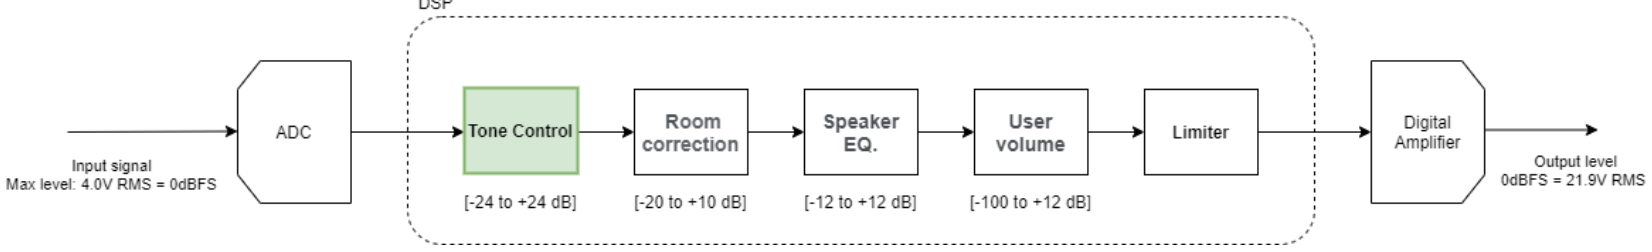

Dette vil vi gøre ved at konstruere to shelving-filtre i kaskade hvor den ene er til bas og den anden til diskant. Kravene er således:

- 2 x IIR filtre (shelving)

- Niveau i hvert bånd +-24dB

## Analyse

Den tonekontrol vi skal bygge bliver en simplificeret udgave af en equalizer med double band indeholden cut og boost af inputsignalet. Det vil sige equalizere former af lydspektret ved at forbedre visse frekvenser bands, mens andre forbliver upåvirket. Måden dette kan gøres på er ved at bruge shelving filtre. Vi konstuere herved to shelving filtre og kaskade kobler dem. På denne måde får vi lavet et band for de lavefrekvenser og et band for de højefrekvenser, derudover kommer der også et tilhørende band for de individuelle cut-off frekvenser.

Et 1. ordens shelving filter har et slope af frekvenskurven på 6 dB per octave, men i dette miniprojekt ønskes et større slope. Det vil sige stejler hældning, hvilket er derfor vi konsturere 2. ordens shelving filtre. Til konstuktionen af shelving IIR filtrene gøres brug af formlerne fra Table 2.3 se **figur XX**. Tabellen beskriver formlerne for de 3 "b" koeficienter og de 2 "a" koeficienter, da "a0" altid er 1. For at kunne bruge formlerne til koeficenterne skal "K" og "V0" beregnes, som der også ses formler til i Table 2.3 se **figur XX**.

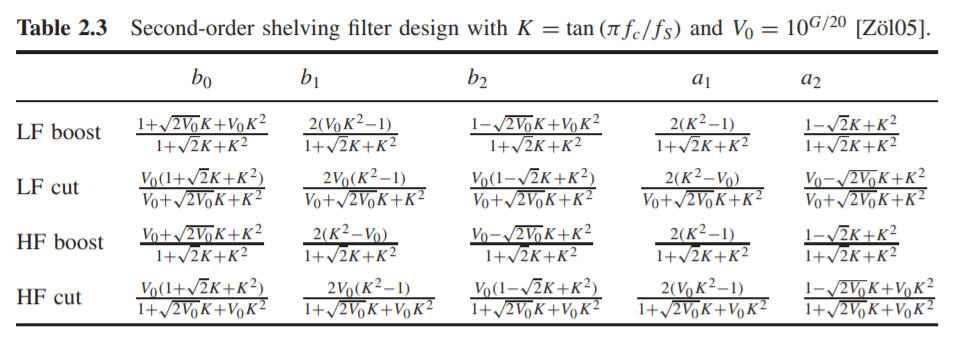

### *FilterSelect *funktion

## Anvendelse af *Tonekontrol*

%Fs  = 44100;    % Sampelfrekvens
[limbo,Fs]=audioread("Limbo.mp3");

Fcb         = 80;      % Cutoff for bass
Fct         = 3500;     % Cutoff for treble

gainBass    =16;       % Gain for bass
gainTreble  =-12;       % Gain for treble

[Bbas,Abas] = FilterSelect(Fs,gainBass,Fcb,"bass");         % b og a koeffitienter for bass
[Btreb,Atreb] = FilterSelect(Fs,gainTreble,Fct,"treble");   % b og a koeffitienter for treble

Hbas=dfilt.df2t(Bbas,Abas);     % IIR filter for bass
Htreb=dfilt.df2t(Btreb,Atreb);  % IIR filter for treble
Hcas=dfilt.cascade(Hbas,Htreb); % Kaskade kobling af de to IIR filtre


 
filteretLimbo=filter(Hcas,limbo);
soundsc(filteretLimbo,Fs)

 
soundsc(limbo,Fs)

 
clear sound

ddmkds

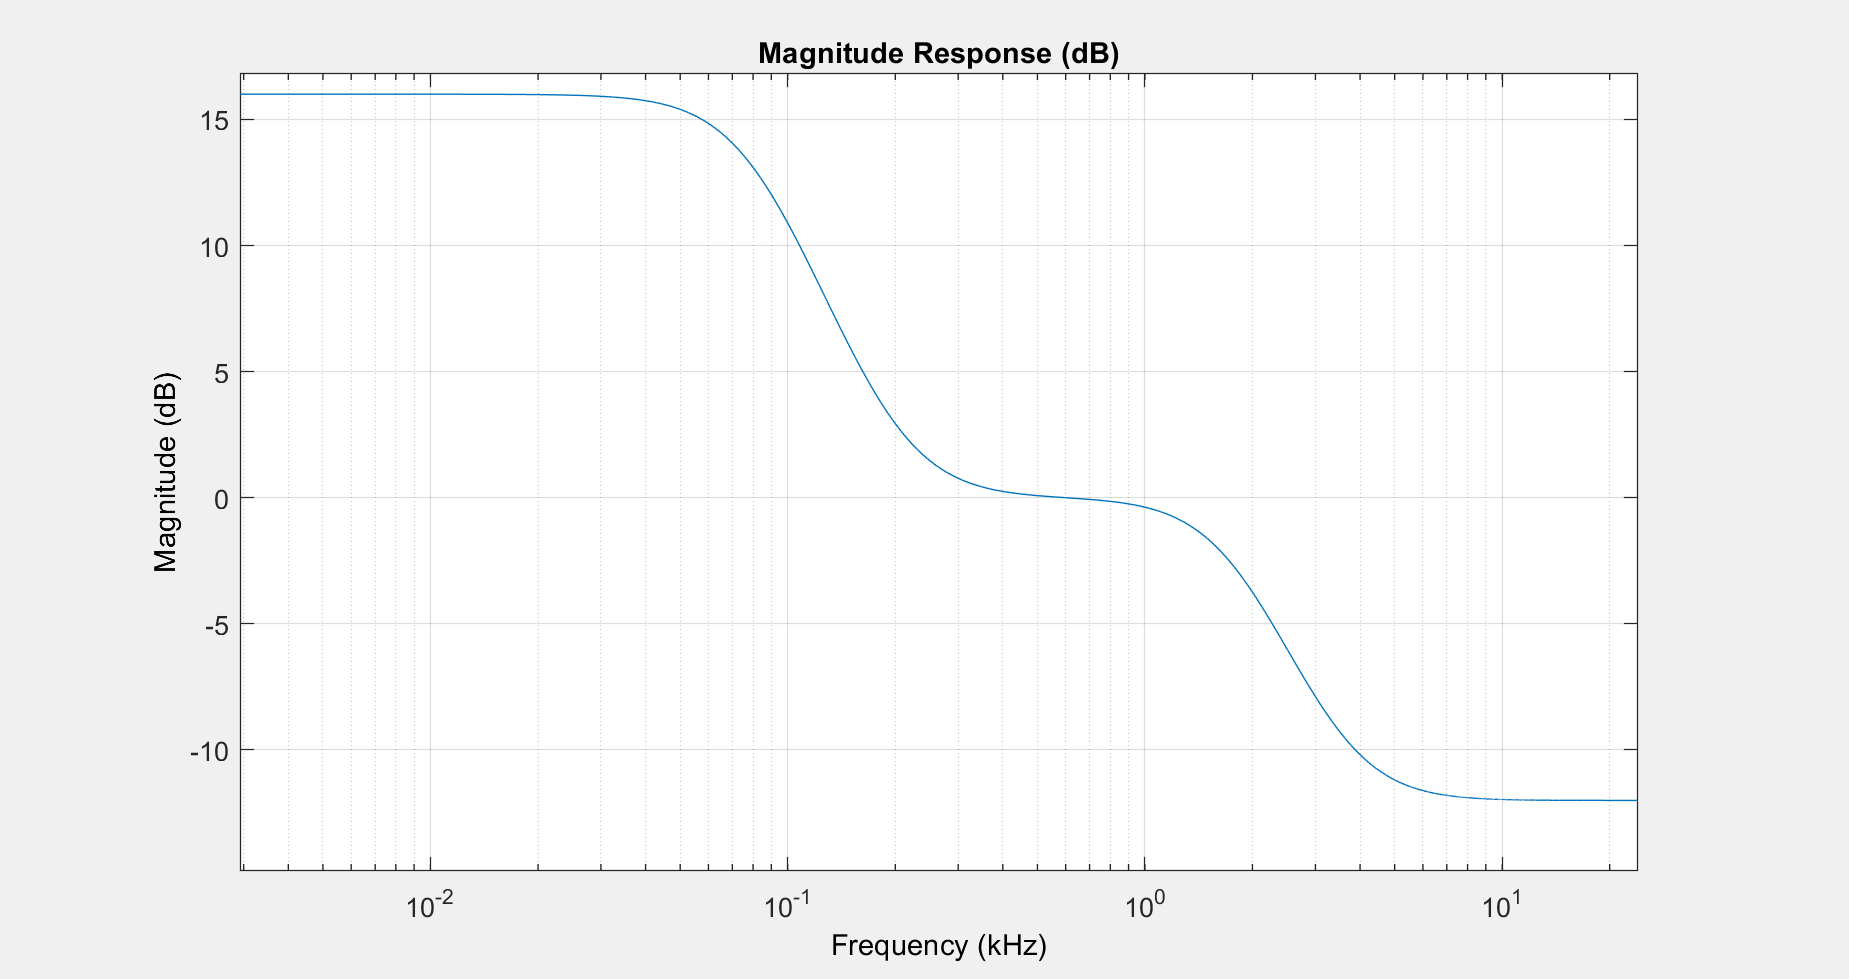

fvtool(Hcas, 'Analysis', 'magnitude', 'Fs', Fs);

dfkopsdsd

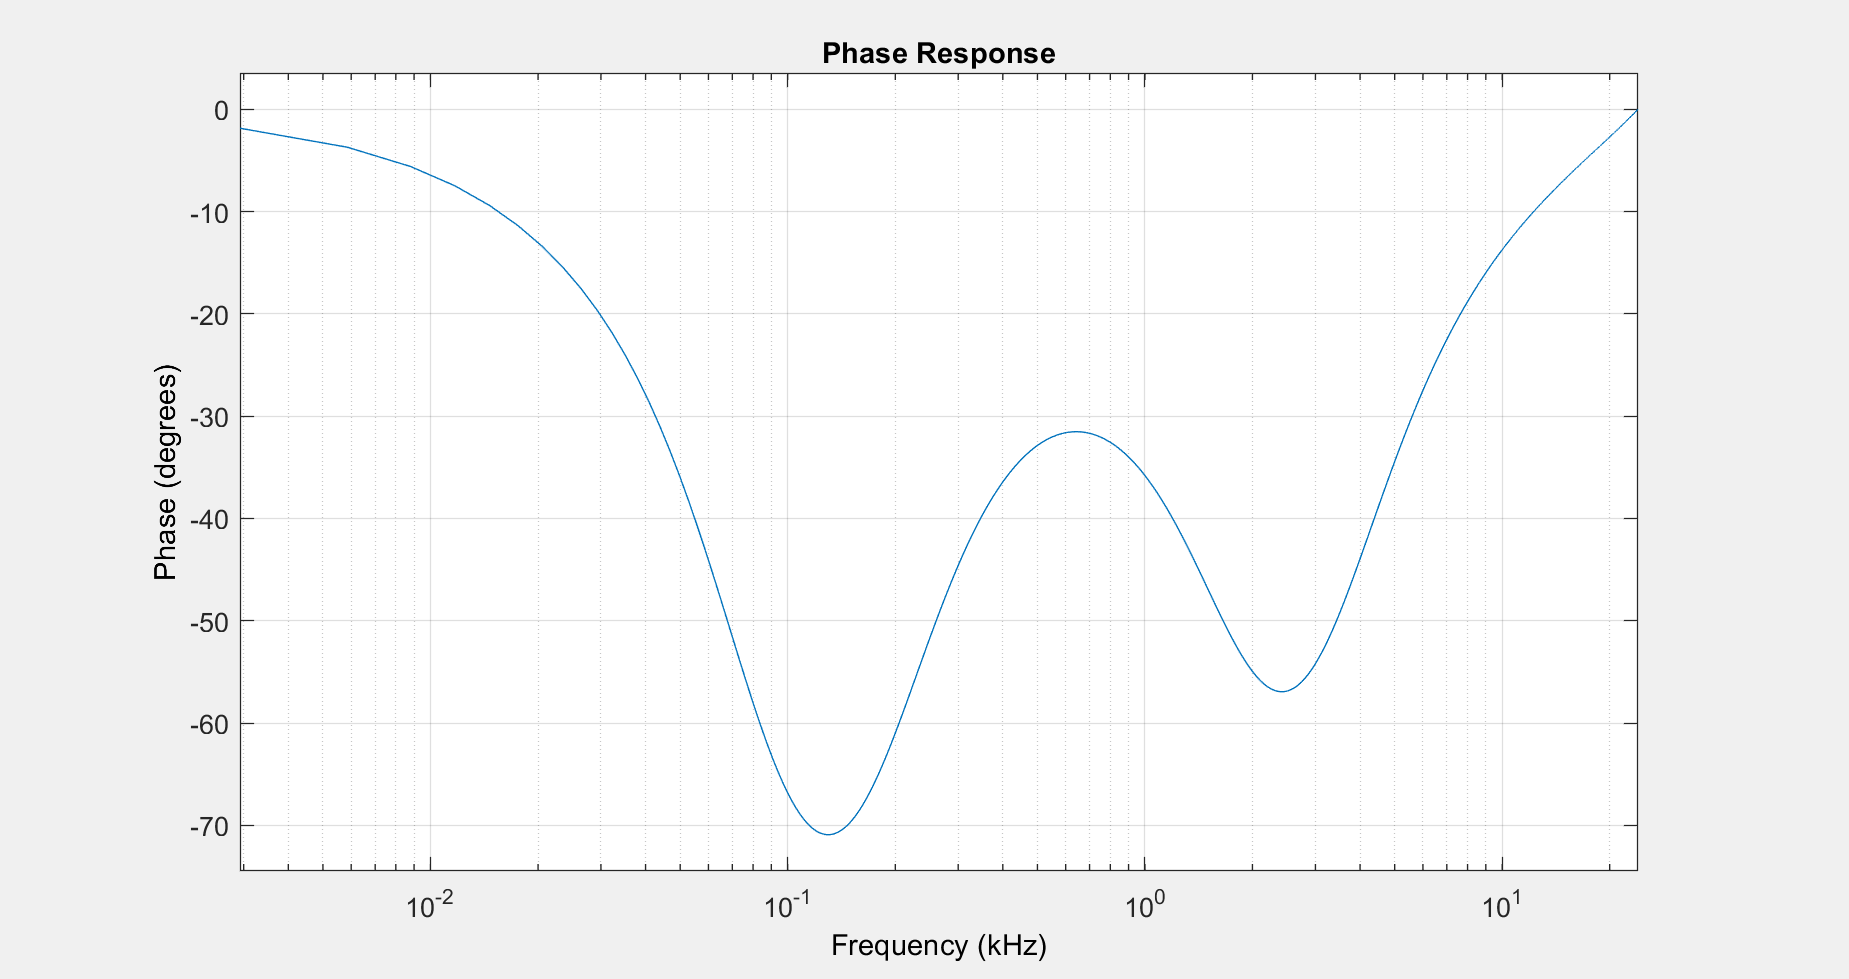

fvtool(Hcas, 'Analysis', 'phase', 'Fs', Fs);

fdsklvksd

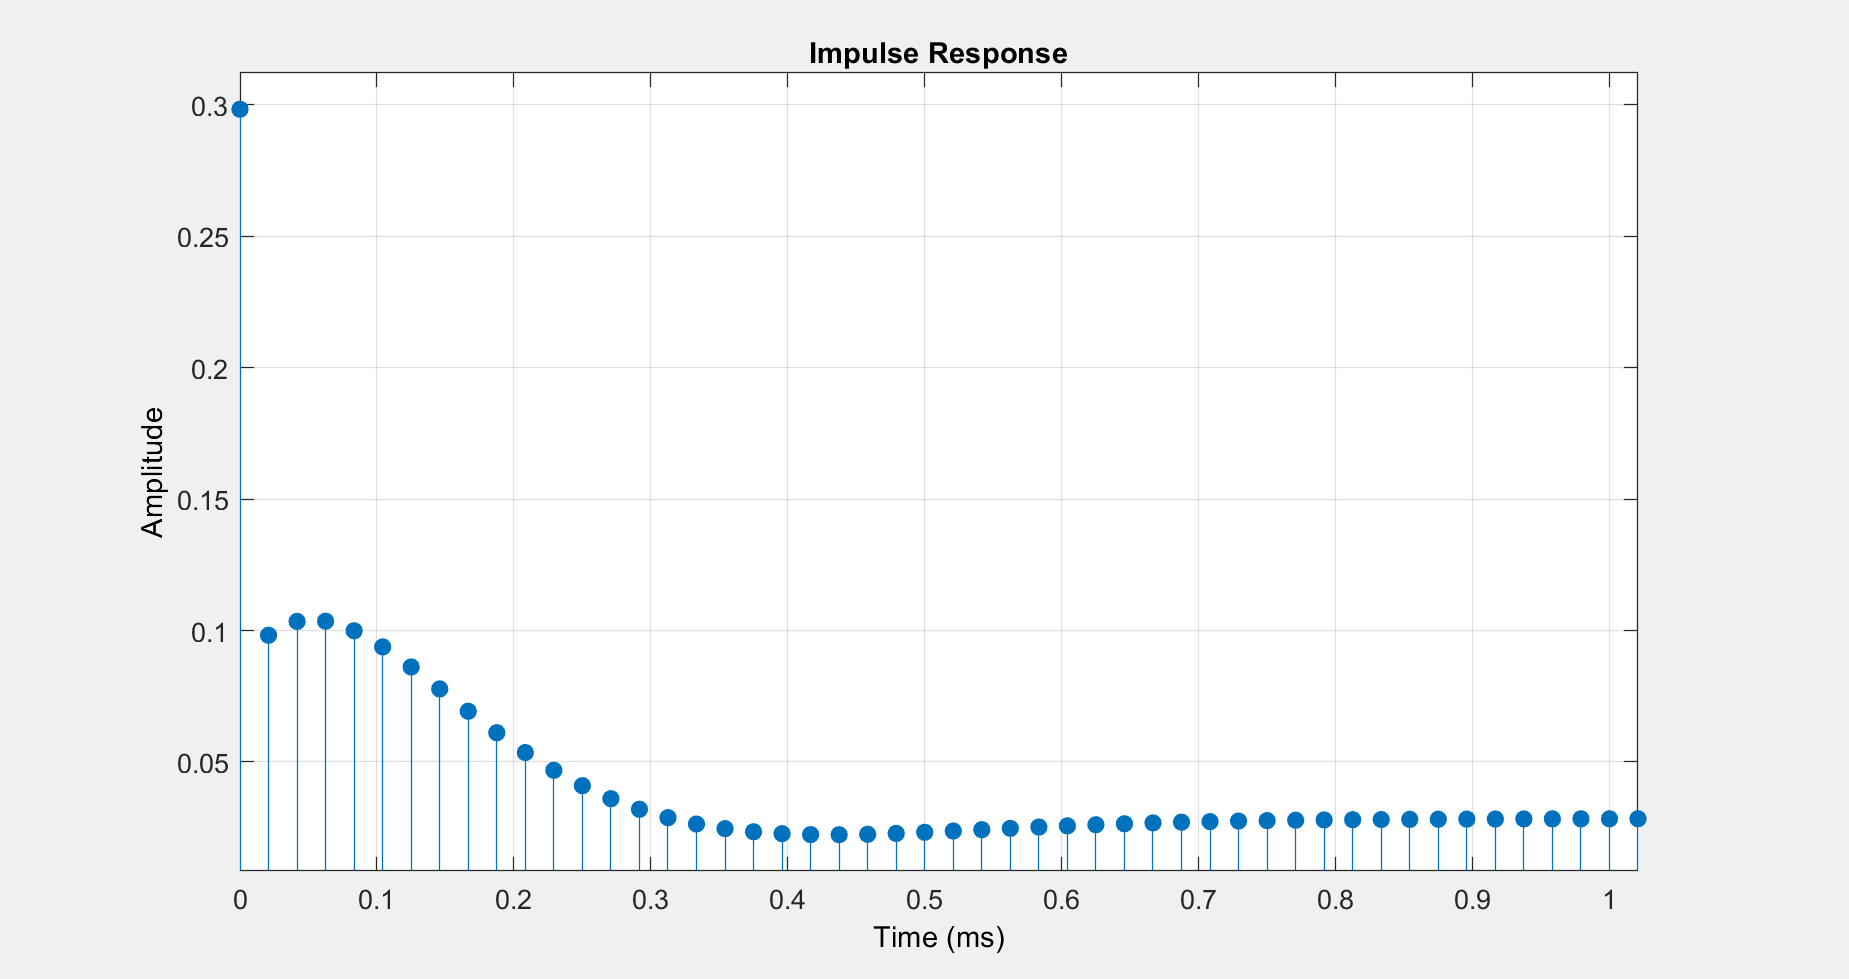

fvtool(Hcas, 'Analysis', 'impulse', 'Fs', Fs);

## Konklusion